clear all
close all

robot = robot_3R()

robot =   rigidBodyTree with properties:

     NumBodies: 4
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'link_1'  'link_2'  'link_3'  'link_ee'}
      BaseName: 'base'
       Gravity: [0 0 0]
    DataFormat: 'column'


th_r = robot.homeConfiguration;
th_dot_r = 0*th_r;
th_a = robot.homeConfiguration;
th_dot_a = 0*th_a;
num_states = 3;
num_cart = 2;

dt = 0.005;
t_end = 5;
t_span = 0:dt:t_end;

for i = 1:length(t_span)
    tau = 1*(2*rand(num_states,1) - 1);
    [th_a(:,i+1), th_dot_a(:,i+1)] = dynamics_3R(tau,th_a(:,i), th_dot_a(:,i));
    x_a(:,i) = forward_map_3R_real(th_a(:,i));

    th_ddot = forwardDynamics(robot,th_r(:,i),th_dot_r(:,i),tau);
    th_dot_r(:,i+1) = th_dot_r(:,i) + th_ddot*dt;
    th_r(:,i+1) = th_r(:,i)+ th_dot_r(:,i)*dt + (1/2)*th_ddot*dt^2;

    htf = getTransform(robot, th_r(:,i), 'link_ee');
    x_r(:,i) = htf(1:num_cart,4);
end

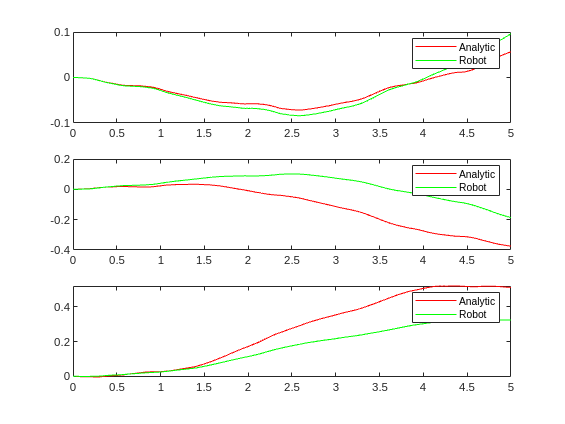

figure()
for i = 1:num_states
    subplot(3,1,i)
    xlabel('t')
    ylabel(strcat('th',num2str(i)))
    plot(t_span,th_a(i,1:end-1),'r',t_span,th_r(i,1:end-1),'g')
    legend('Analytic', 'Robot')

end

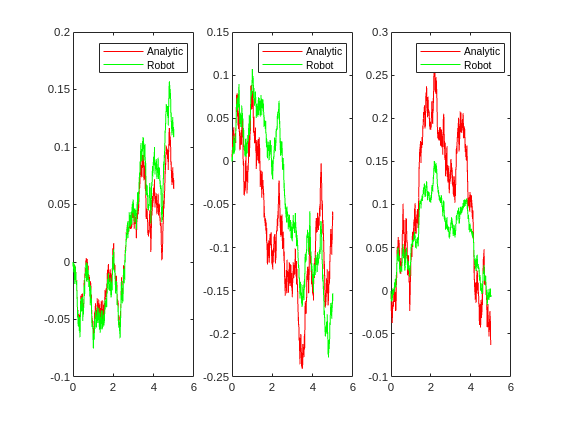

figure()
for i = 1:num_states
    subplot(1,3,i)
    xlabel('t')
    ylabel(strcat('th dot ',num2str(i)))
    plot(t_span,th_dot_a(i,1:end-1),'r',t_span,th_dot_r(i,1:end-1),'g')
    legend('Analytic', 'Robot')

end

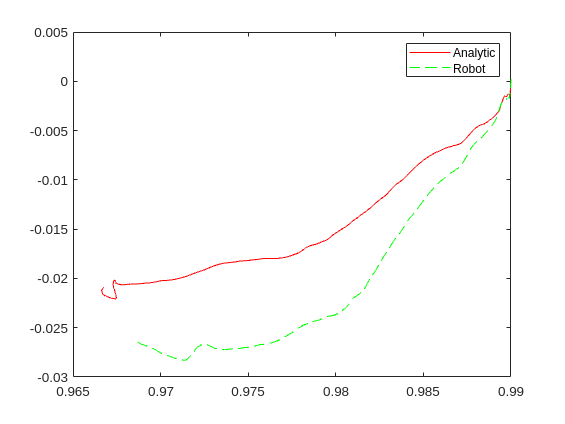

figure()
plot(x_a(1,:),x_a(2,:), 'r',x_r(1,:),x_r(2,:), 'g--')
legend('Analytic', 'Robot')